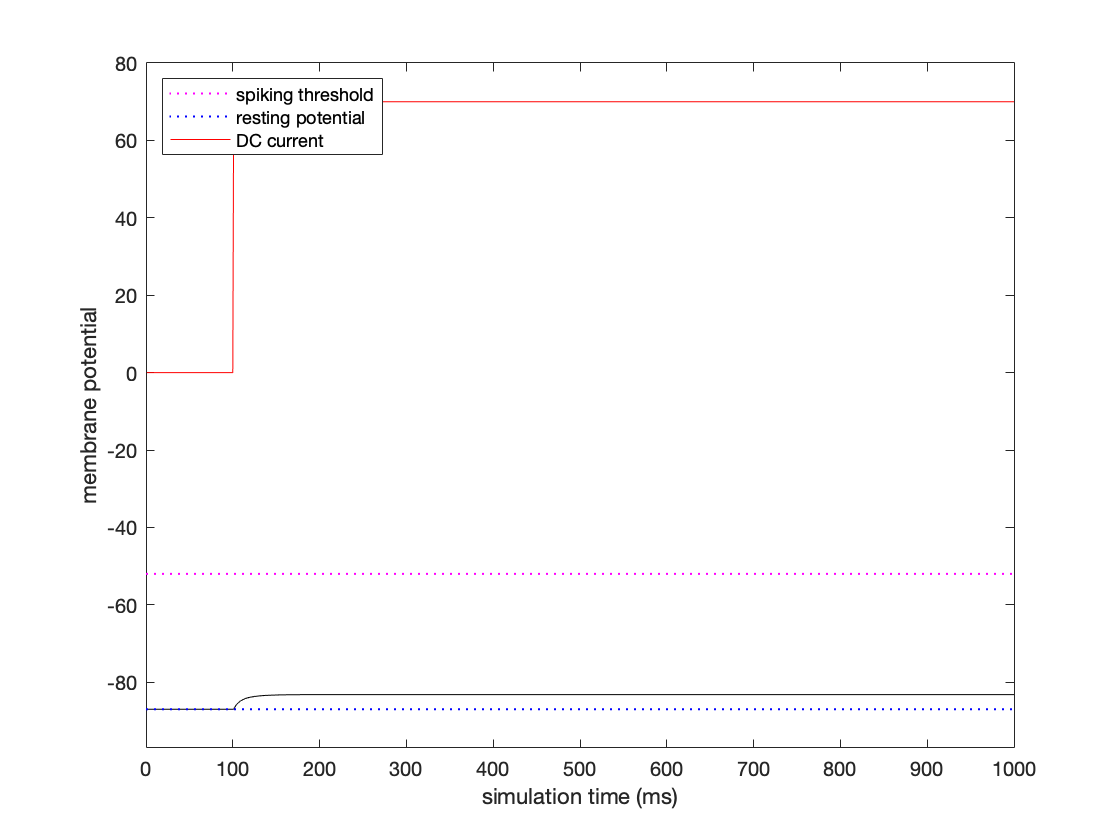

% Define membrane parameters...
params.mem.C  = 160;         % membrane capacitance
params.mem.k  = 0.7;
params.mem.vr = -87;        % resting membrane potential
params.mem.vt = -52;         % instantaneous threshold potential
params.mem.a  = 0.09;        % recovery time constant
params.mem.b  = -3.4;        % determines whether u is amplifying (b<0) or resonant(b>0)
params.mem.vpeak = 41;        % spike cutoff
params.mem.c  = -50;        % voltage reset value
params.mem.d  = 170;         % total outward-inward current during spike

% ...and stimulus parameters
params.stm.I          = 70;                         % stimulation amplitude (current)
params.stm.dt         = 0;
params.stm.T          = 1000;                       % total time of stimulation (ms)
params.stm.t          = 1;                          % time step of stimulation (ms)
params.stm.pulseWidth = 0.9;  % width of stimulation pulse (fraction of total time)
params.stm.dt         = params.stm.T*(1 - params.stm.pulseWidth);


% initialize/calculate some parameters
n = round(params.stm.T/params.stm.t); % simulation time steps
I = [zeros(1,int32((1-params.stm.pulseWidth)*n)),...
    params.stm.I*ones(1,int32(params.stm.pulseWidth*n))]; % DC current
v = params.mem.vr*ones(1,n); u = 0*v; % initial values for membrane potential & recovery

% simulate the model
for ii = 1:n-1
    v(ii+1)=v(ii)+params.stm.t*(params.mem.k*(v(ii)-params.mem.vr)*(v(ii)-params.mem.vt)-u(ii)+I(ii))/params.mem.C;  % membrane potential
    u(ii+1)=u(ii)+params.stm.t*params.mem.a*(params.mem.b*(v(ii)-params.mem.vr)-u(ii));                   % membrane rec variable
    
    % if spike occurs, reset membrane potential and recovery variable
    if v(ii+1)>=params.mem.vpeak
        v(ii)= params.mem.vpeak;
        v(ii+1)=params.mem.c;
        u(ii+1)=u(ii+1)+params.mem.d;
    end
end
output = v;

% plot the simulation
plotIzhikevichSimulation(output,params.stm.t*(1:n),I,params.mem.vr,params.mem.vt)

function [value,isterminal,direction] = events(t,y,pars)
vpeak      = pars(7);                % Back out the parameters for better readability 
T          = pars(12);
value      = [y(2) - vpeak; T - t];  % And then define the zeros that we need to detected

isterminal = [1;1];   % Stop the integration when zero is detected
direction  = [1;0];   % [Detect only zeros for increasing values; Detect all zeros]
end

function plotIzhikevichSimulation(v,t,I,vr,vt)
% inputs: 
% v = simulated membrane potential
% t = time steps of simulation
% I = stimulation current pulse
% vr = resting membrane potential
% vt = instantaneous threshold potential
%-----------------------------------------------------------------
% plot the results
plot(t,v,'k'); hold on  % plot the membrane potential
cp = plot(t,I,'r');     % plot the stimulus pulse
% show resting membrane potential and spiking threshold on the figure
vrl = line([0 max(t)],[vr vr],'color','b','LineStyle',':','LineWidth',1);
vtl = line([0 max(t)],[vt vt],'color','m','LineStyle',':','LineWidth',1);
% plot aesthetics
ylim([vr-10 max(I)+10])
legend([vtl,vrl,cp],{'spiking threshold','resting potential','DC current'},"Location","northwest")
hold off
xlabel('simulation time (ms)')
ylabel('membrane potential')
end